# EX 7.1

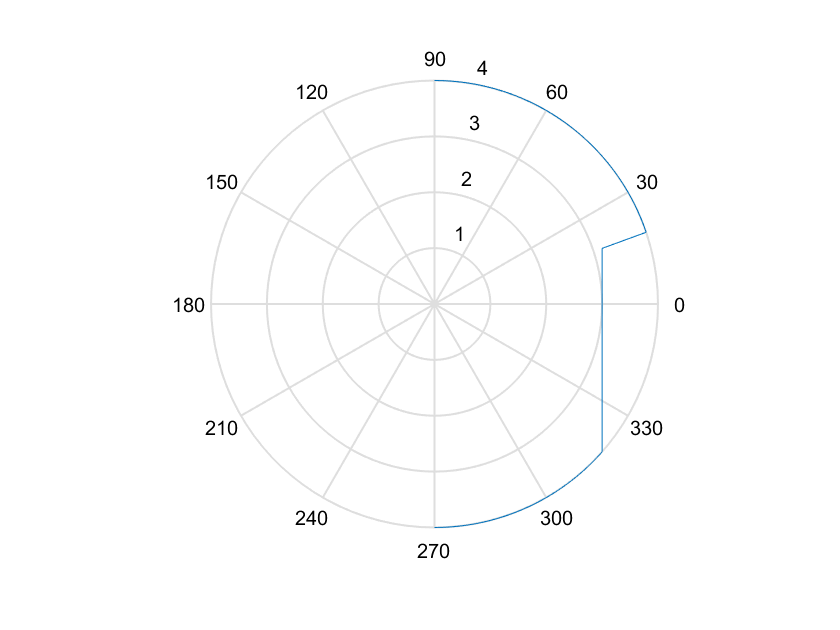

close all;
lines = [3,-4,3,1]';
x_l = 0;
y_l = 0;
theta_l = 0;
dist = 4;
resol=0.36;
fov = 180;
scan_pol = laserscan2011(x_l, y_l, theta_l, lines, dist, resol,fov);
polar(scan_pol(1,:),scan_pol(2,:))

## EX 7.2

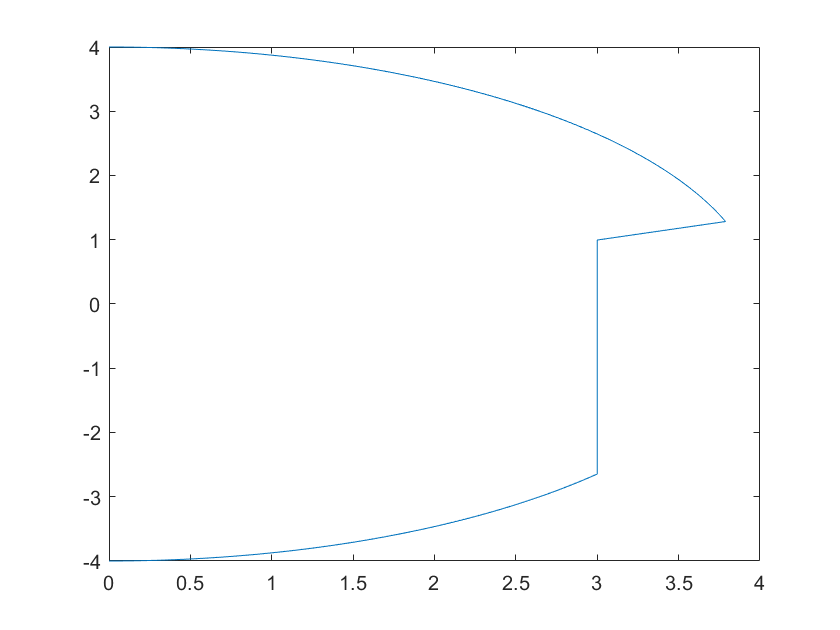

[x,y] = pol2cart(scan_pol(1,:),scan_pol(2,:));
plot(x,y)

## EX 7.3

res = transform(x,y,x_l,y_l,theta_l);
plot(res(1,:),res(2,:))

## EX 7.4.1

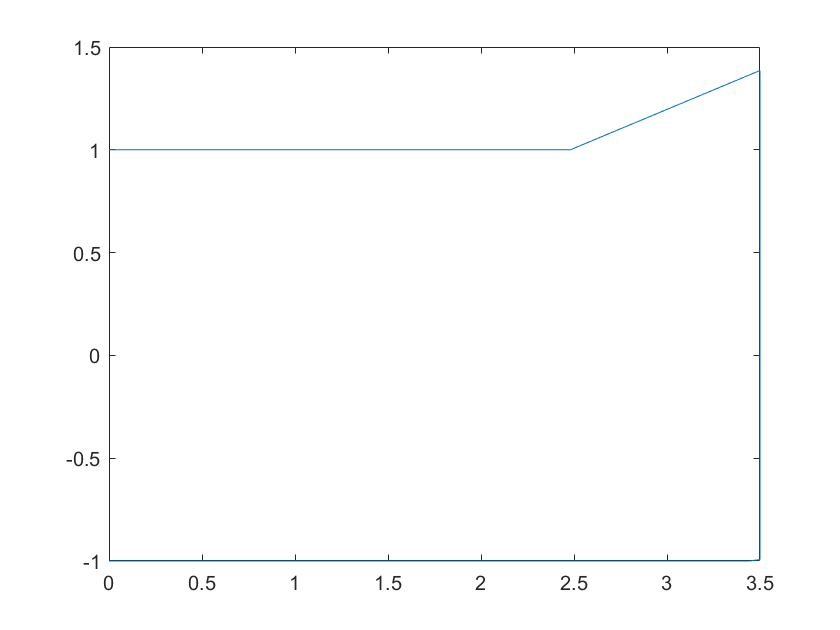

lines1 = [0,1,2.5,1]';
lines2 = [2.5,1,2.5,5]';
lines3 = [0,-1,3.5,-1]';
lines4 = [3.5,-1,3.5,5]';
lines_env = [lines1,lines2,lines3,lines4];
scan_pol = laserscan2011(x_l, y_l, theta_l, lines_env, dist, resol,fov);
[x,y] = pol2cart(scan_pol(1,:),scan_pol(2,:));
res = transform(x,y,x_l,y_l,theta_l);
plot(res(1,:),res(2,:))

## EX 7.4.2

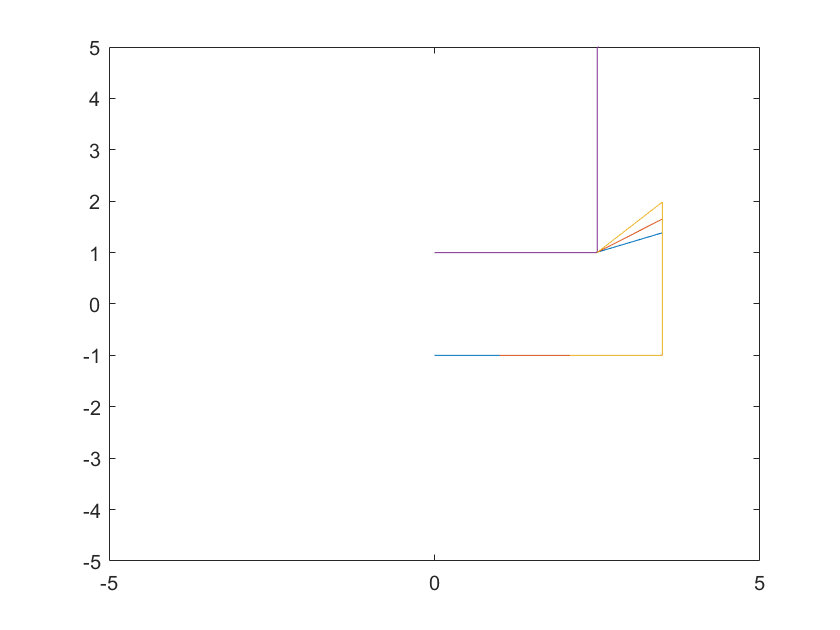

pos1 = [0 0 0]';
pos2 = [1 0 0]';
pos3 = [1.5 0 pi/6]';
pos4 = [0 4 0]';
pos_env = [pos1,pos2,pos3,pos4];
figure;
for idx = 1:numel(pos_env(1,:))
    scan_pol = laserscan2011(pos_env(1,idx), pos_env(2,idx), pos_env(3,idx), lines_env, dist, resol,fov);
    [x,y] = pol2cart(scan_pol(1,:),scan_pol(2,:));
    res = transform(x,y,pos_env(1,idx), pos_env(2,idx), pos_env(3,idx));
    plot(res(1,:),res(2,:))
    hold on
end
xlim([-5 5])
ylim([-5 5])

## Ex 7.5

% X = 5
y = linspace(-5,5,100);
x = 5*ones(1,length(y));
[a,r]=lsqline(x,y)

a = 8.7756e-17

r = 5

% y = 3
x = linspace(-10,10,1000);
y = 3*ones(1,length(x));
[a,r]=lsqline(x,y)

a = 1.5708

r = 3

% x+y+3=0
x = linspace(-5,5,100);
y = -x-3;
[a,r]=lsqline(x,y)

a = -2.3562

r = 2.1213

function [alpha,r] = lsqline(x,y)
    n = length(x);
    Ex = sum(x);
    Ey = sum(y);
    Exy = x*y';
    Exx = x*x';
    Eyy = y*y';
    x_ = (1/n)*Ex;
    y_ = (1/n)*Ey;
    alpha = atan2((2*Ex*Ey-2*n*Exy),(Ex^2-Ey^2-n*Exx+n*Eyy))/2;
    r = abs(x_ * cos(alpha) + y_ * sin(alpha));
    if (alpha<-0.001)
        alpha = alpha + pi;
    elseif (alpha>0.001)
        alpha = alpha - pi;
    end
end

function res = transform(x,y,x_l,y_l,theta_l)
    res = [cos(theta_l) -sin(theta_l);sin(theta_l) cos(theta_l)]*[x;y]+[x_l;y_l];
end